1. 原始图像

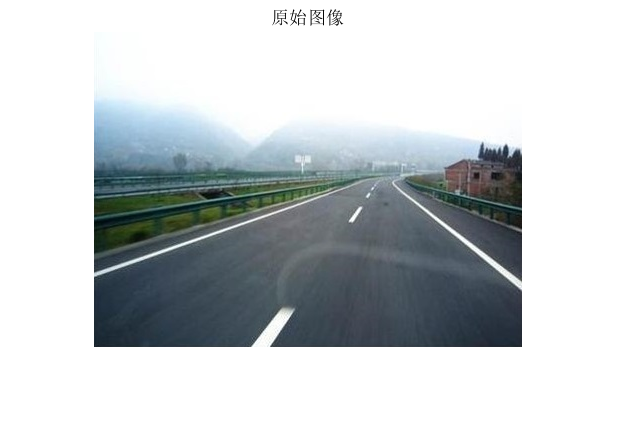

I=imread('图片2.jpg');
figure(1)
imshow(I)
title('原始图像')

2. 图像灰度化

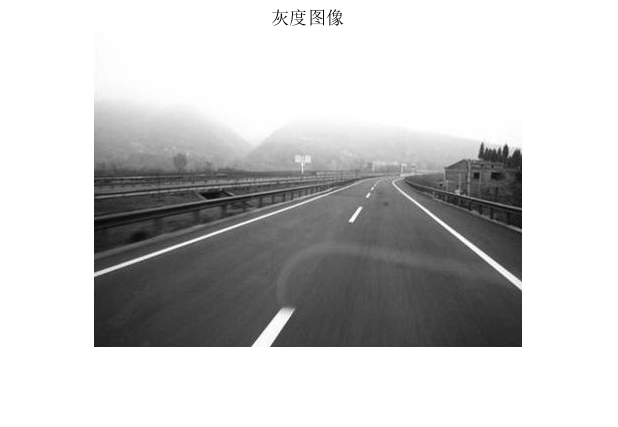

I1=rgb2gray(I);
figure(2)
imshow(I1)
title('灰度图像')

3. 图像滤波

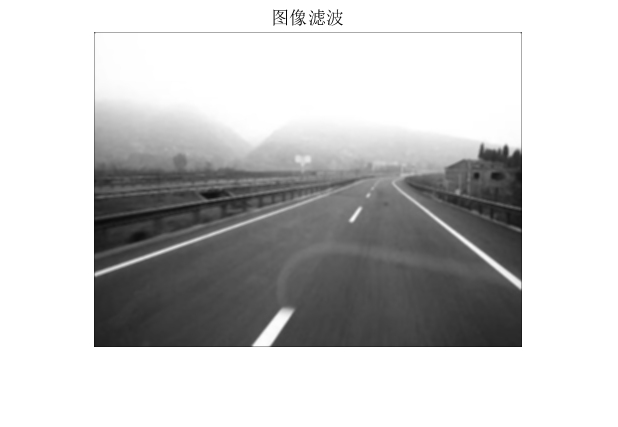

I21=medfilt2(I1);                           % 高斯滤波
I22=filter2(fspecial('average',3),I21)/255; % 平滑滤波
figure(3)
imshow(I22)
title('图像滤波')

4. 图像二值化

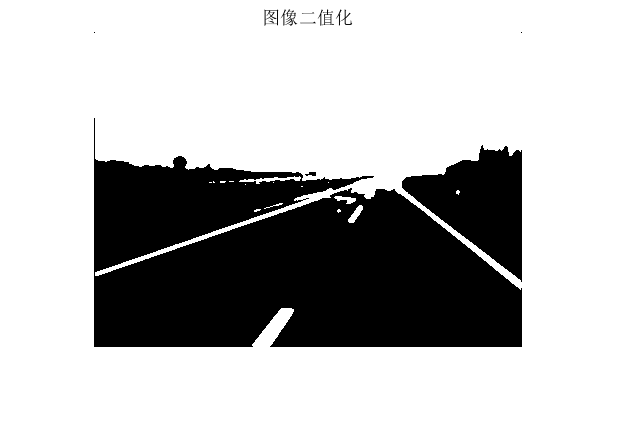

I3=im2bw(I22);
figure(4)
imshow(I3)
title('图像二值化')

5. 图像边缘检测

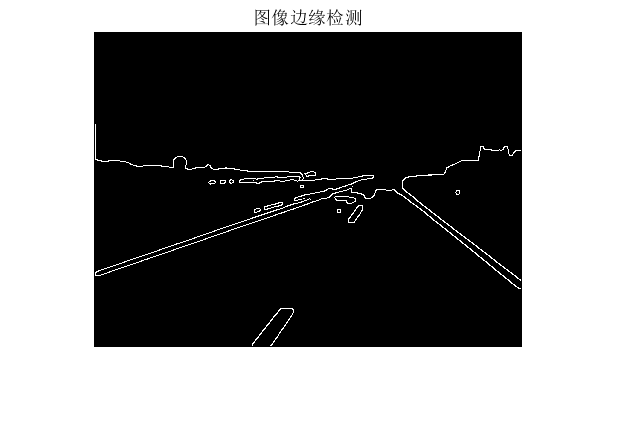

I4=edge(I3, 'canny');
figure(5)
imshow(I4)
title('图像边缘检测')

6. 霍夫变换

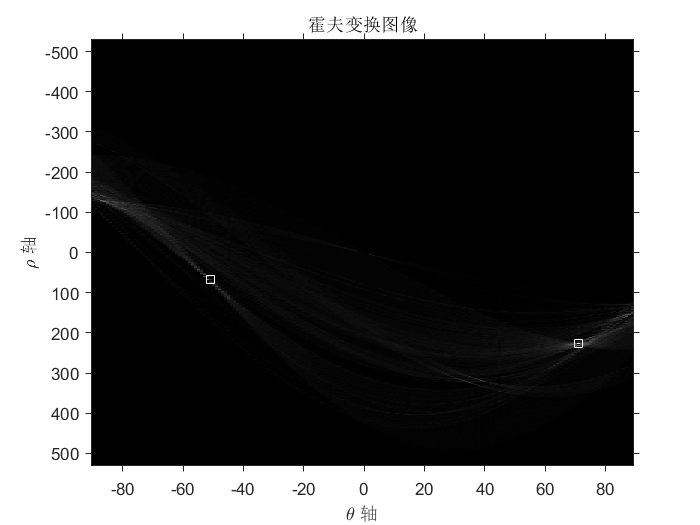

[H,T,R]=hough(I4);
figure(6)
imshow(H,[], 'XData',T, 'YData',R, 'InitialMagnification', 'fit')
title('霍夫变换图像')
xlabel('\theta 轴')
ylabel('\rho 轴')
axis on,axis normal

hold on
P=houghpeaks(H,2, 'threshold',ceil(0.3*max(H(:)))); 
x=T(P(:,2));
y=R(P(:,1));
plot(x,y, 's', 'color', 'white')
hold off

7. 车道线检测

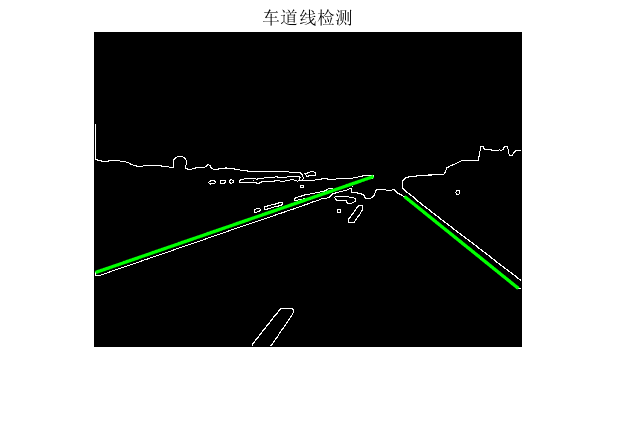

lines=houghlines(I4,T,R,P, 'FillGap',50, 'MinLength',50);	
figure(7)
imshow(I4)
title('车道线检测')	
hold on
for i=1:length(lines)
    xy = [lines(i).point1; lines(i).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
end

hold off